## **Driver test program to check Clothoids library**

**Biarcs**

Comparison of biarc and arc  passing from 3 points, the 3rd point is the junction of the biarc

ok1 = logical
   1


ok2 = logical
   1


ok1 = logical
   1


ok2 = logical
   1


ok1 = logical
   1


ok2 = logical
   1


ok1 = logical
   1


ok2 = logical
   1


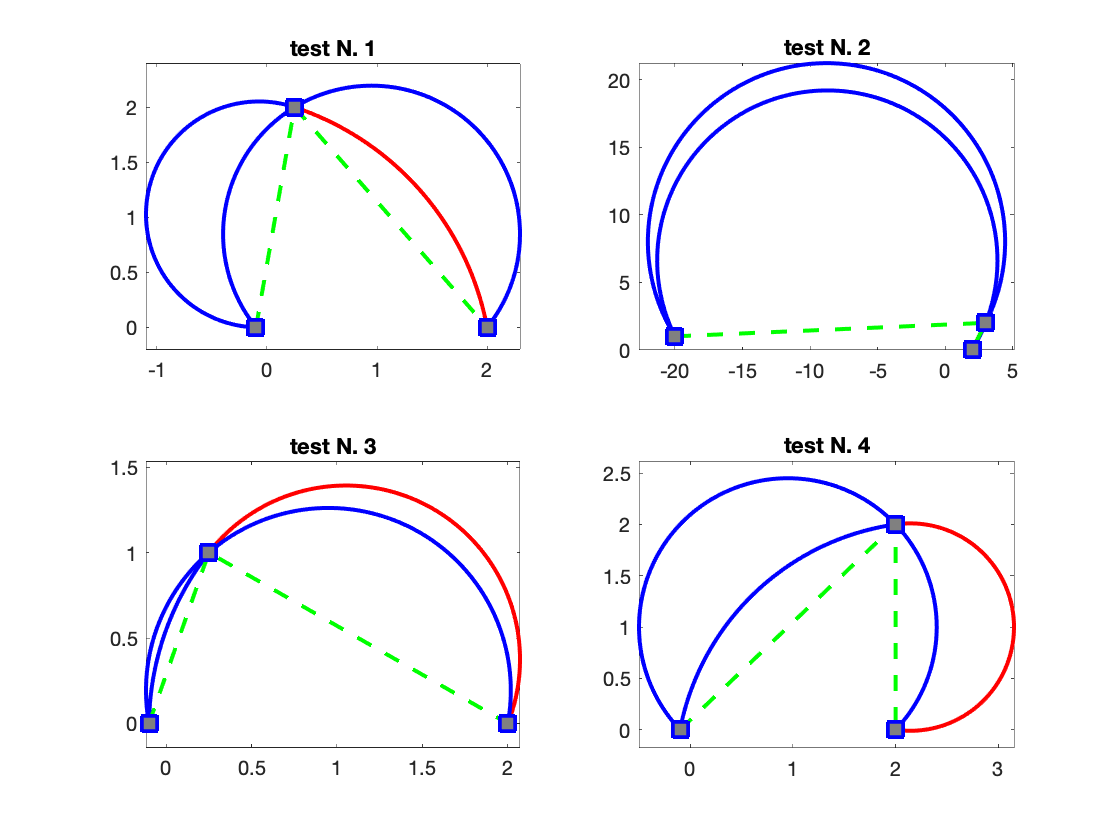

close all;

x0=[-0.1,-20,-0.1,-0.1];
y0=[ 0,1,0,0];
x1=[ 1/4,2+1,1/4,2];
y1=[ 2,2,1,2];
x2=[ 2,2,2,2];
y2=[0,0,0,0];

B = Biarc();
A = CircleArc();
for kk=1:4
  
  subplot(2,2,kk);

  ok1 = B.build_3P( x0(kk), y0(kk), x1(kk), y1(kk), x2(kk), y2(kk) );
  ok2 = A.build_3P( x0(kk), y0(kk), x1(kk), y1(kk), x2(kk), y2(kk) );

  ok1
  ok2
  
  fmt1 = {'-g','LineWidth',2};
  fmt2 = {'-r','LineWidth',2};
  
  B.plot(1000);%,fmt1,fmt2);
  A.plot();

  plot( [x0(kk),x1(kk),x2(kk)],[y0(kk),y1(kk),y2(kk)], ...
        '--gs',...
        'LineWidth',2,...
        'MarkerSize',10,...
        'MarkerEdgeColor','b',...
        'MarkerFaceColor',[0.5,0.5,0.5]);
  title(sprintf('test N. %d',kk));
  axis equal;
end